clc; clear all; close all;

Digitalni filtry ve zpracovani audia

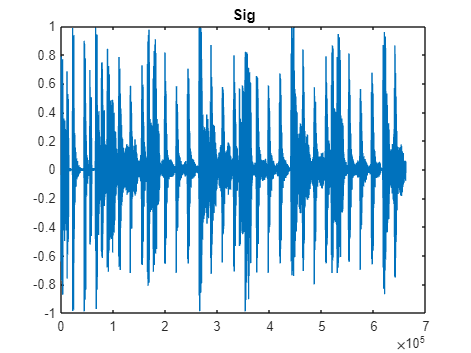

[x, Fs] = audioread("H Mim.wav");
x = x(Fs*30:Fs*45, :);
plot(x(:,1))
title("Sig")

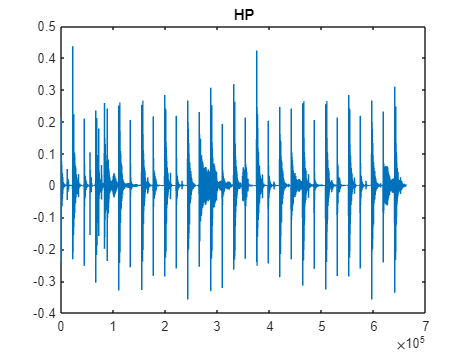


Fc = 1000;
% jina moznost vytvoreni filtru nez filterDesigner
B = fir1(1000, Fc/(Fs/2), 'high');
load("HPFilter.mat")

y_HP = filter(HPFilter, 1, x);
plot(y_HP(:,1))
title("HP")

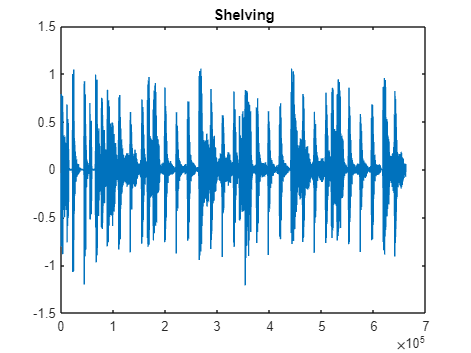


V = 1;
y_S = x + V*y_HP;
plot(y_S(:,1))
title("Shelving")


% sound(y_S/3, Fs)

filtr posunul o 500 vzorku, takze x musime posunout o 500 vzorku

500 vzorku, protoze je filtr radu 1000

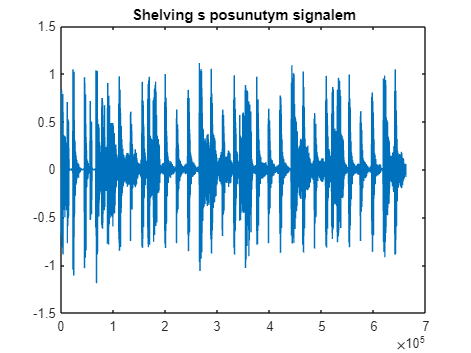

y_S = [zeros(500, 2); x(1:end-500, :)]+V*y_HP;
plot(y_S(:, 1))
title("Shelving s posunutym signalem")

% fvtool(1+V*HPFilter)
% sound(y_S/3, Fs)

Neco jinyho

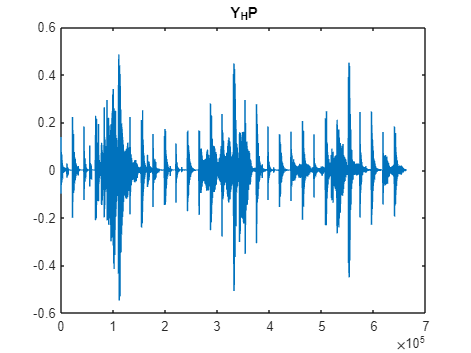

Fc = 1000;
jak_rychle_kroutim = 0.2;
y_HP = zeros(size(x));
y_AP = zeros(size(x));
for n = 2:length(x)
    Fc = 100 + 2500*(cos(2*pi*jak_rychle_kroutim*n/Fs) + 1);
    c = (tan(pi*Fc/Fs)-1)/(tan(pi*Fc/Fs)+1);
    y_AP(n, :) = c*x(n, :) + x(n-1, :) - c*y_AP(n-1, :);
    y_HP(n, :) = (x(n, :) - y_AP(n, :))/2;
end
plot(y_HP(:, 1))
title("Y_HP")